clear; 
s0_add_paths;

# Create the image features

nOri = 8; nSurroundOrient = 8;
nCentOrient = 4;
orientations = linspace(0, pi, nOri+1);
orientations = orientations(1:end-1);
surrOrient = orientations;
centOrient  = orientations(1:2:8); 
numpix  = 400;
fovs    = 12.5 * [1, 3/2, 1, 1]; % deg (the second data set had a larger field of view than the others)
fov     = fovs(1);
pixperdeg = numpix / fov;
ppc     = round(pixperdeg./3); % pixels per cycle

num     = numpix; % number of pixels in 2 cycles
surroundSize = round(pixperdeg * 8);
centerSize = round(pixperdeg * 4);
picMask = gen_disk(num, surroundSize, 1);
cenMask = gen_disk(num, centerSize, 1);

[x, y]  = meshgrid((0:num - 1)/ppc);

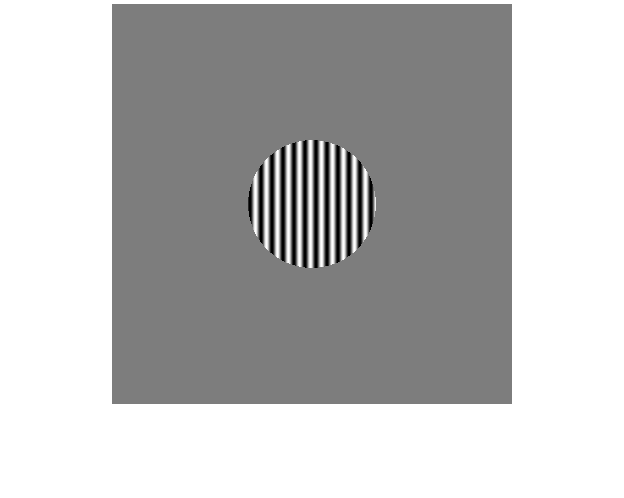

% get the center feature
i = 1;
theta = orientations(i);
wave_c = cos(theta);
wave_s = sin(theta);
h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
I_center = cenMask.*real(h);
figure();
imshow(I_center, []);

### The stimuli with surround suprresion

Images vary across 8 surround orientations and 4 center orientations

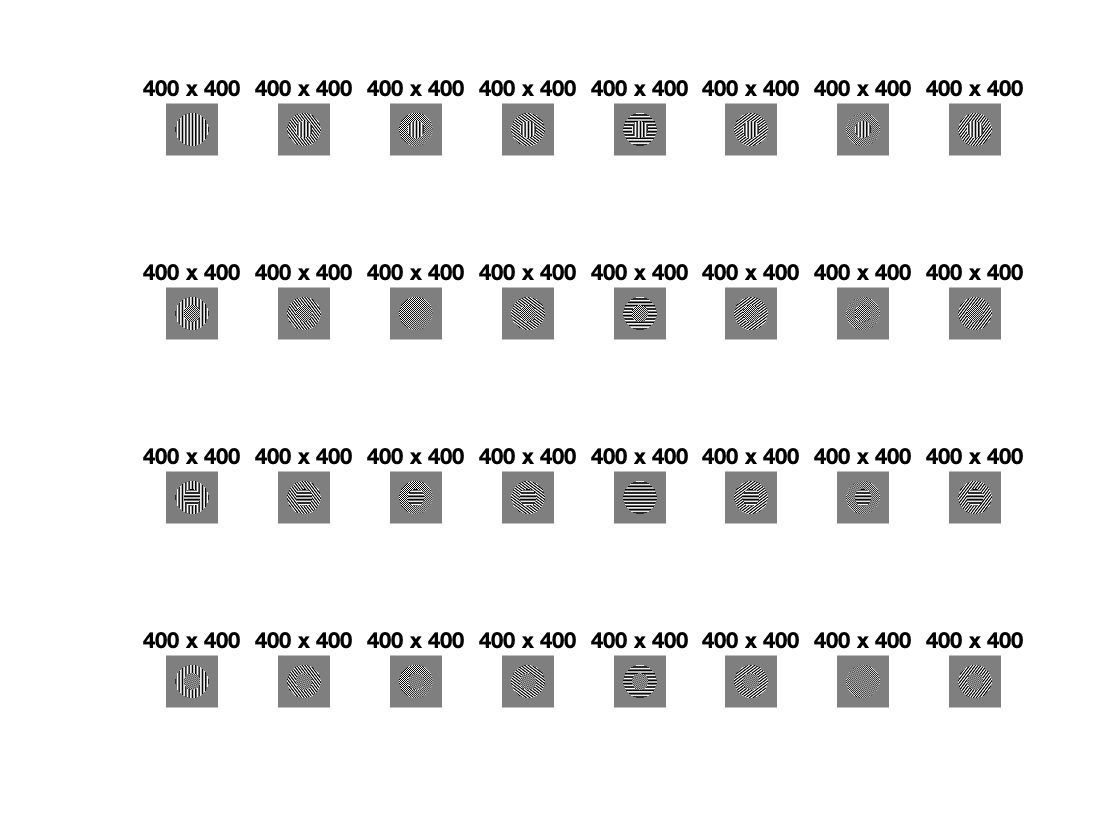

surr_stim = cell(nSurroundOrient, nCentOrient);
for i = 1:nSurroundOrient
    for j = 1:nCentOrient
        % Center
        [x, y]  = meshgrid((0:num- 1)/ppc);
        theta = centOrient(j);
        wave_c = cos(theta);
        wave_s = sin(theta);
        h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
        center = 0.5*(cenMask.*real(h));
        
        % Surround
        theta = surrOrient(i);
        wave_c = cos(theta);
        wave_s = sin(theta);
        h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
        h = real(h);
        surr = 0.5*(picMask.*h.*(1-cenMask));
        
        surr_stim{i, j} = surr + center;
    end
end
figure();
for i = 1:nCentOrient 
    for j = 1:nSurroundOrient
        subplot(nCentOrient, nSurroundOrient, (i-1)*nSurroundOrient+j)
        imshow(surr_stim{j, i}, [])
        n = size(surr_stim{j, i}, 1);
        title(sprintf('%d x %d', n, n))
    end
end

## Stimuli used to create tuning curve

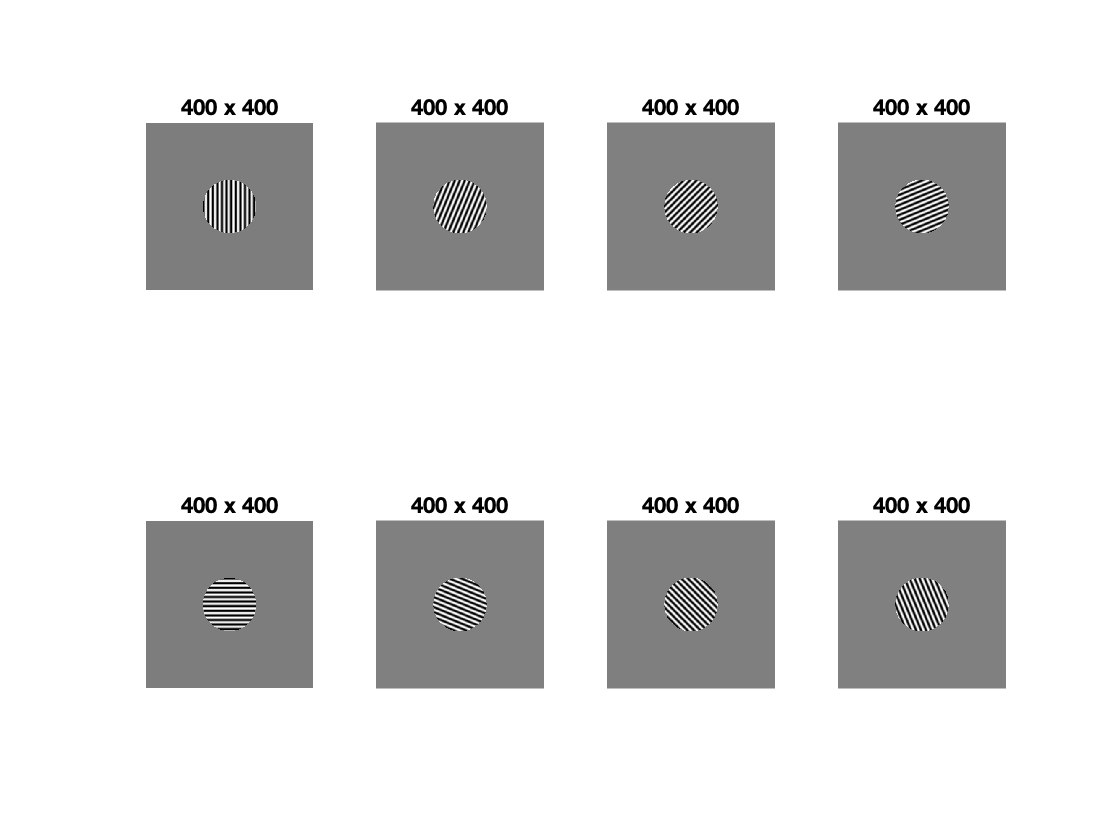

tune_stim = cell(nCentOrient, 1);
for i = 1:nOri
    [x, y]  = meshgrid((0:num- 1)/ppc);
    theta = orientations(i);
    wave_c = cos(theta);
    wave_s = sin(theta);
    h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
    tune_stim{i,1} = .5*(cenMask.*real(h));
end

figure;
for i = 1:nOri
    subplot(2, nOri/2, i)
    imshow(tune_stim{i, 1}, [])
    n = size(tune_stim{i, 1}, 1);
    title(sprintf('%d x %d', n, n))
end

# Frame the problem

### Energy extraction

#### 
$$E(x,y,\theta) = \sum_{\phi}\left(I(x, y)F(x,y,\theta, \phi)\right)^2$$


#### * $I$ the image

#### * $F$ the filter (the neuron)

#### * $x,\;y$ indicates the neuron's location

#### * $x^{\prime } ,y^{\prime } \;$is the neuron's receptive field

#### * $\theta \;$ neuron's preferred orientation

#### * $\phi \;$ the phases, sine or cosine

### Get the filters (Neurons)

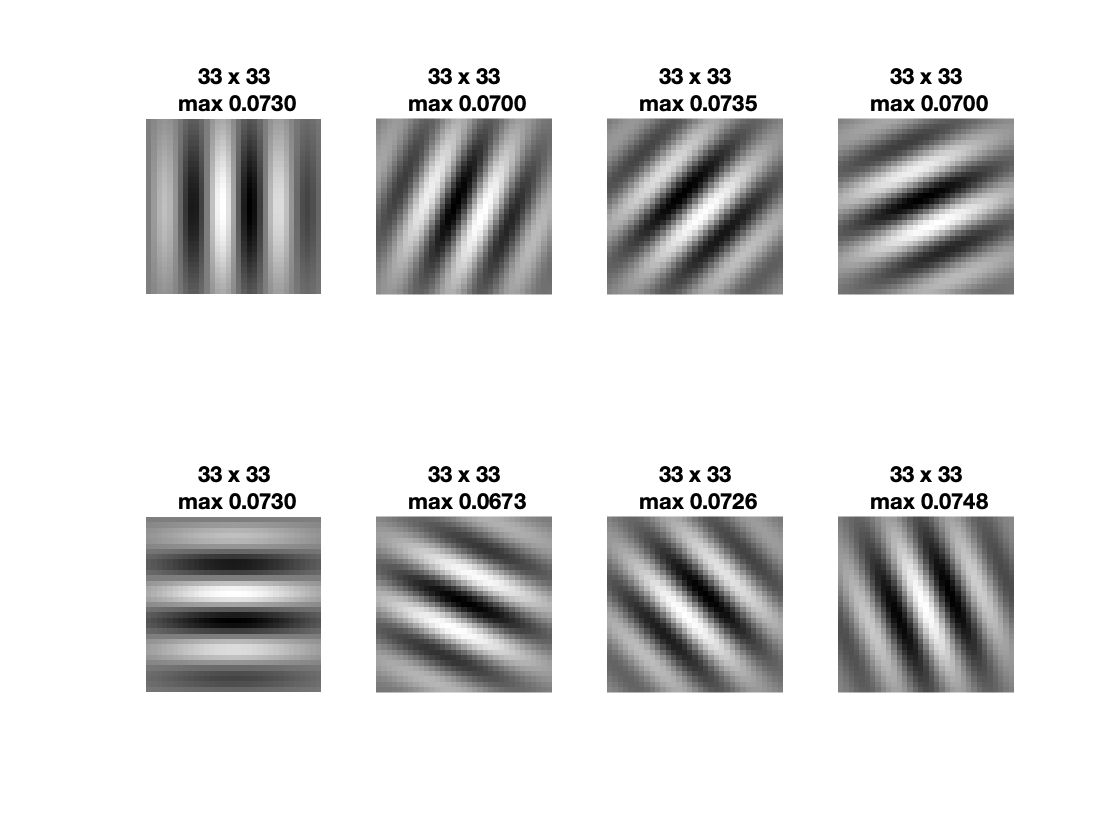

% extract contrast energy
% create filters
supp=3;
figure;
[Gabor_c, Gabor_s] = makeGaborFilter(ppc, orientations, supp);
for i = 1:nOri
    subplot(2, 4, i)
    imshow(Gabor_c{i}, [])
    n = size(Gabor_c{i}, 1);
    title(sprintf('%d x %d\n max %.04f', n, n, max(Gabor_c{i}(:))))
end

### Extract the contrast energy 

% x, y, orient_channnel, surrOri, centOri
tune_E = nan([size(I_center), nOri, nOri]);
surr_E = nan([size(I_center), nOri, nSurroundOrient, nCentOrient]);

for i = 1:nOri
    
    tune_E(:, :, :, i) = Icontrast(tune_stim{i, 1}, Gabor_c, Gabor_s);

    for j = 1:nCentOrient
        surr_E(:, :, :, i, j) = Icontrast(surr_stim{i, j}, Gabor_c, Gabor_s);
    end
end

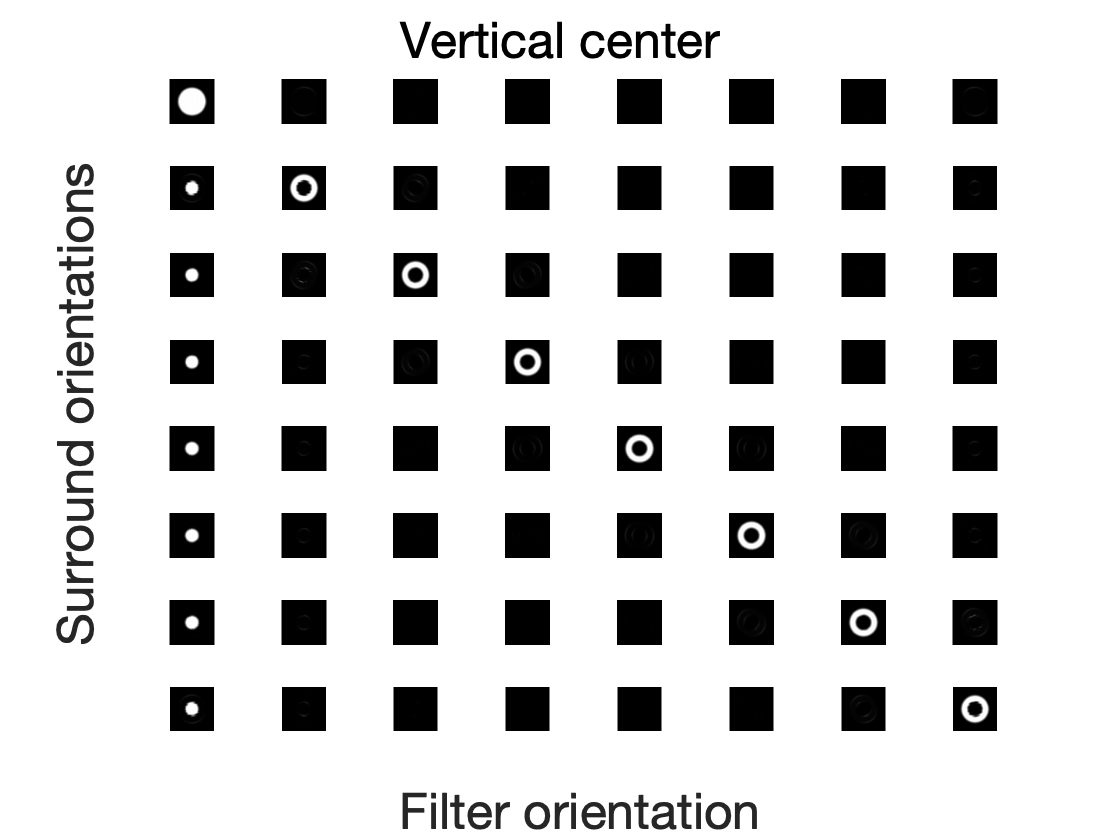

fig = figure;
surr_E1 = surr_E(:, :, :, :, :);
maxe = max(surr_E1(:));
mine = min(surr_E1(:));
for j = 1:nSurroundOrient
    for i = 1:nOri
        subplot(nSurroundOrient, nOri, nOri*(j-1)+i)
        tar = surr_E(:,:,i,j,1);
        imshow(tar, [0, maxe])
        meane = mean(tar(:));
        %title(sprintf('mean E: \n%d', meane))
    end
end

han=axes(fig,'visible','off');
han.XLabel.Visible='on';
han.YLabel.Visible='on';
xlabel(han,'Filter orientation','FontSize', 25);
ylabel(han,'Surround orientations','FontSize', 25);
sgtitle('Vertical center', 'FontSize', 25)

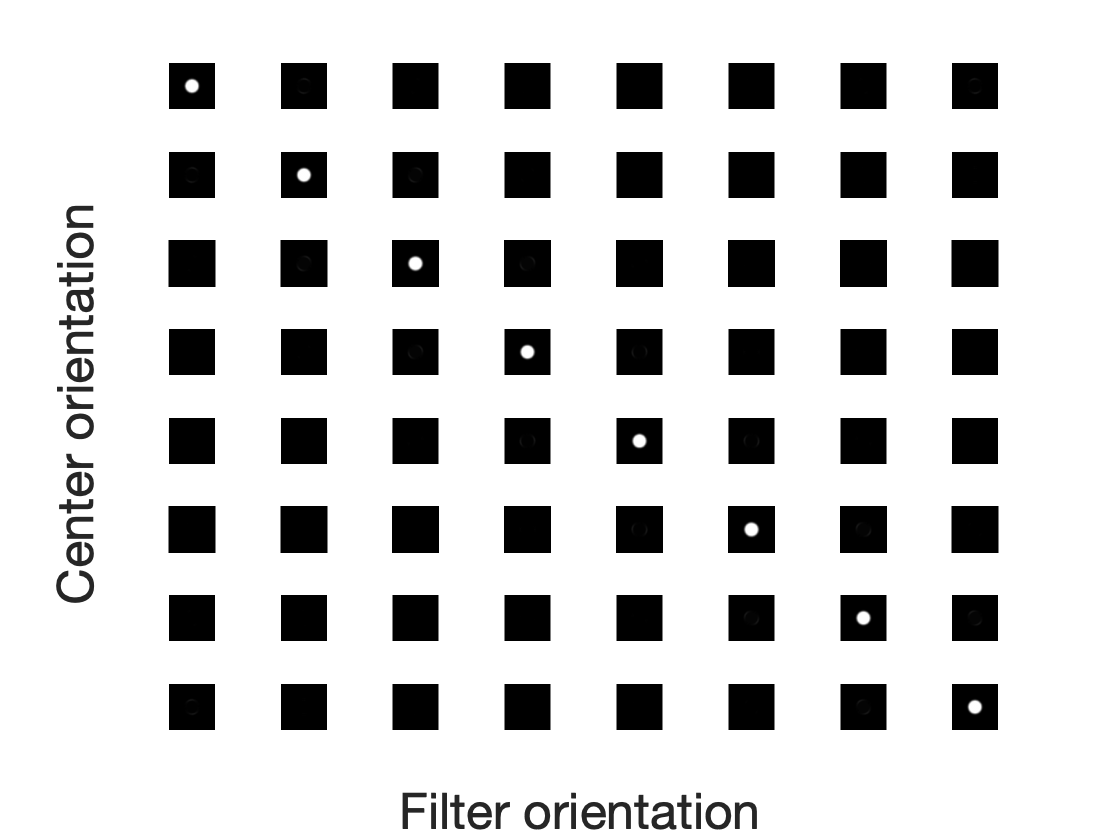

fig = figure;
tune_E1 = tune_E(:, :, :, :);
maxe = max(tune_E1(:));
for j = 1:nOri
    for i = 1:nOri
        subplot(nOri, nOri, nOri*(j-1)+i)
        tar = tune_E(:,:,i, j);
        imshow(tar, [0, maxe])
        meane = mean(tar(:));
        %title(sprintf('mean E: \n%d', meane))
    end
end

han=axes(fig,'visible','off');
han.XLabel.Visible='on';
han.YLabel.Visible='on';
xlabel(han,'Filter orientation','FontSize', 25);
ylabel(han,'Center orientation','FontSize', 25);

# Calculate the neurons' response at the center 

### The general equation that calculate the response is 

#### 
$$d(\theta^c) = \sum_{x,y\in C} \frac{E(x, y, \theta^c)}{\sigma + Z(x,y,\theta^c)}$$


* $Z$ is the normalization

* $C$ is the center area, see the below figure. 

* $\theta^c$ preferred orientation for neurons at the center

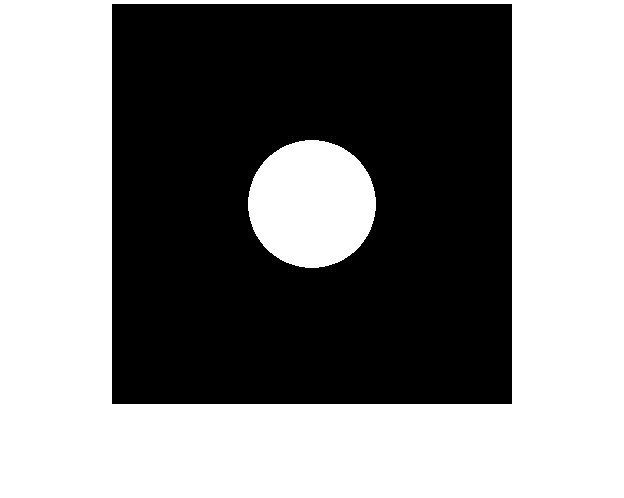

% the center mask: C
figure;
imshow(cenMask, [])

### The CE model 

The model postulates that the normalization is a constant


$$Z = \text{Const}$$


#### A example 

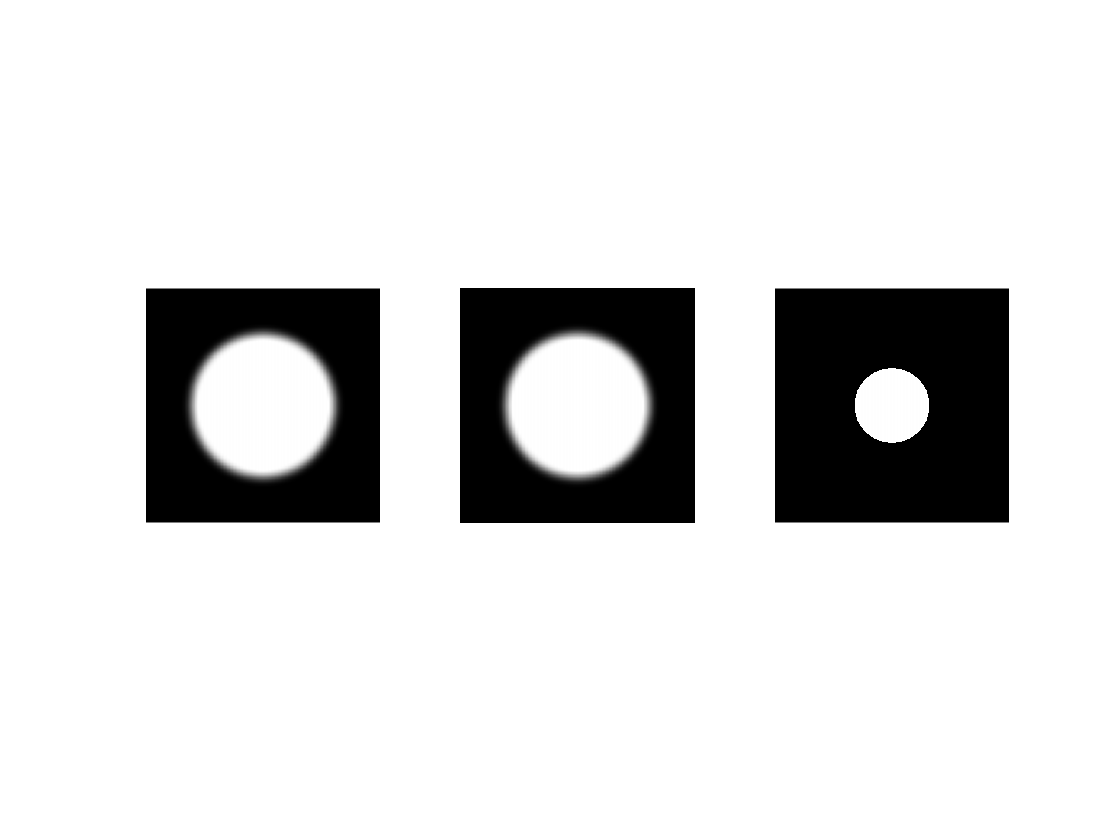

% example for CE model
whichCent = 1;
params = [.1, 1];
sig = params(1); alpha = params(2);
const = 1-sig; 
% energy: % x, y, orient_channnel, surrOri, centOri
E = squeeze(surr_E(:,:,:,:,whichCent));
% get normalizer: Z = const
Z = const;
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = E ./ (sig + Z);
% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(cenMask .* D, [1, 2]));
% add exponential
s = d.^alpha;
% Filter orient x surround orient
r_surrCE = s(whichCent,:); 

figure;
subplot(1, 3, 1)
imshow(squeeze(mean(E(:,:,1), 4)), [])
subplot(1, 3, 2)
imshow(squeeze(mean(D(:,:,1), 4)), [])
subplot(1, 3, 3)
imshow(squeeze(mean(cenMask.*D(:,:,1), 4)), [])

params = [.1, 1];
sig = params(1); alpha = params(2);
const = 1-sig; 
% energy: % x, y, orient_channnel, surrOri, centOri
E = squeeze(tune_E(:,:,:,whichCent));
% get normalizer: Z = const
Z = const;
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = E ./ (Z + sig);
% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(cenMask .* D, [1, 2]));
% add exponential
s = d.^alpha;
r_centCE = s; 

#### Get the curves

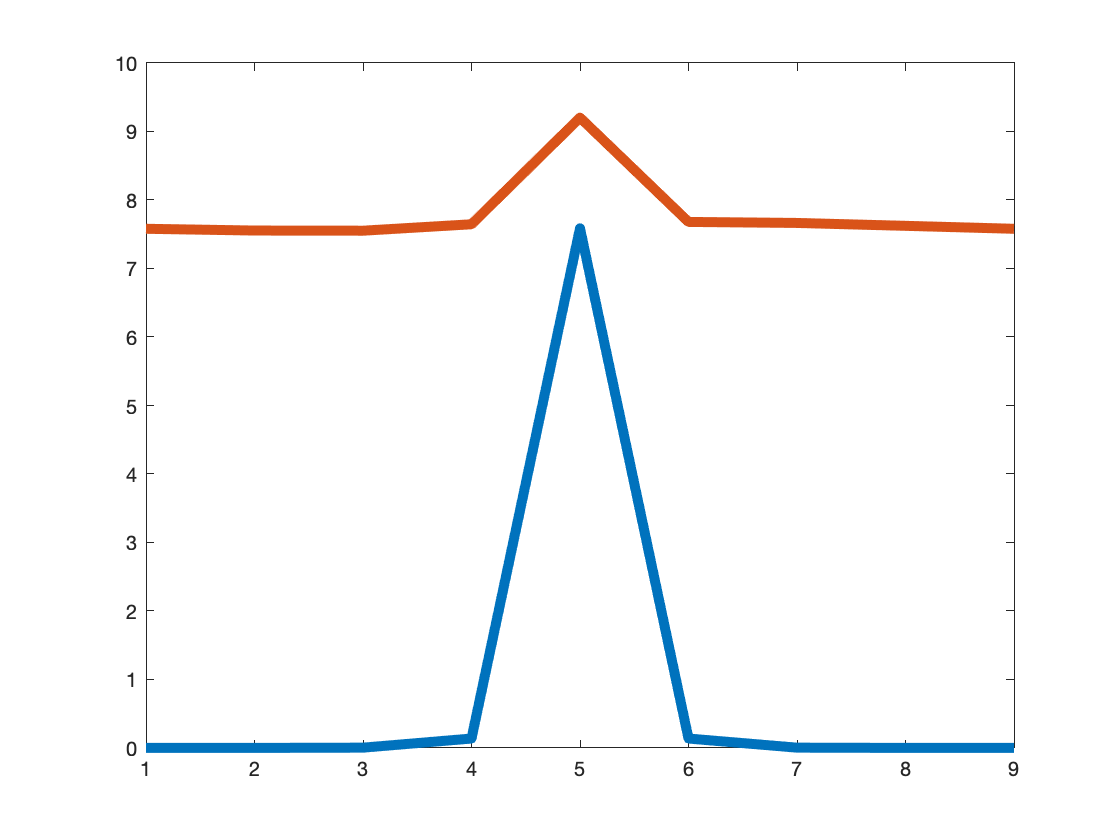

tune_curve      = zeros(1,nCentOrient);
tune_curve(1:4) = r_centCE(5:8);
tune_curve(5:8) = r_centCE(1:4);

supp_curve      = zeros(1,nCentOrient);
supp_curve(1:4) = r_surrCE(5:8);
supp_curve(5:8) = r_surrCE(1:4);

tune_curve2 = [tune_curve, tune_curve(1)];
supp_curve2 = [supp_curve, supp_curve(1)];

figure();
plot(tune_curve2,'LineWidth', 5)
hold on
plot(supp_curve2,'LineWidth', 5)

### The OTS model 

The model postulates that the normalization is a constant


$$Z(\theta) = \sum_{x',y',\theta'} E(x', y', \theta)F(x', y', \theta';\theta)$$


#### A example 

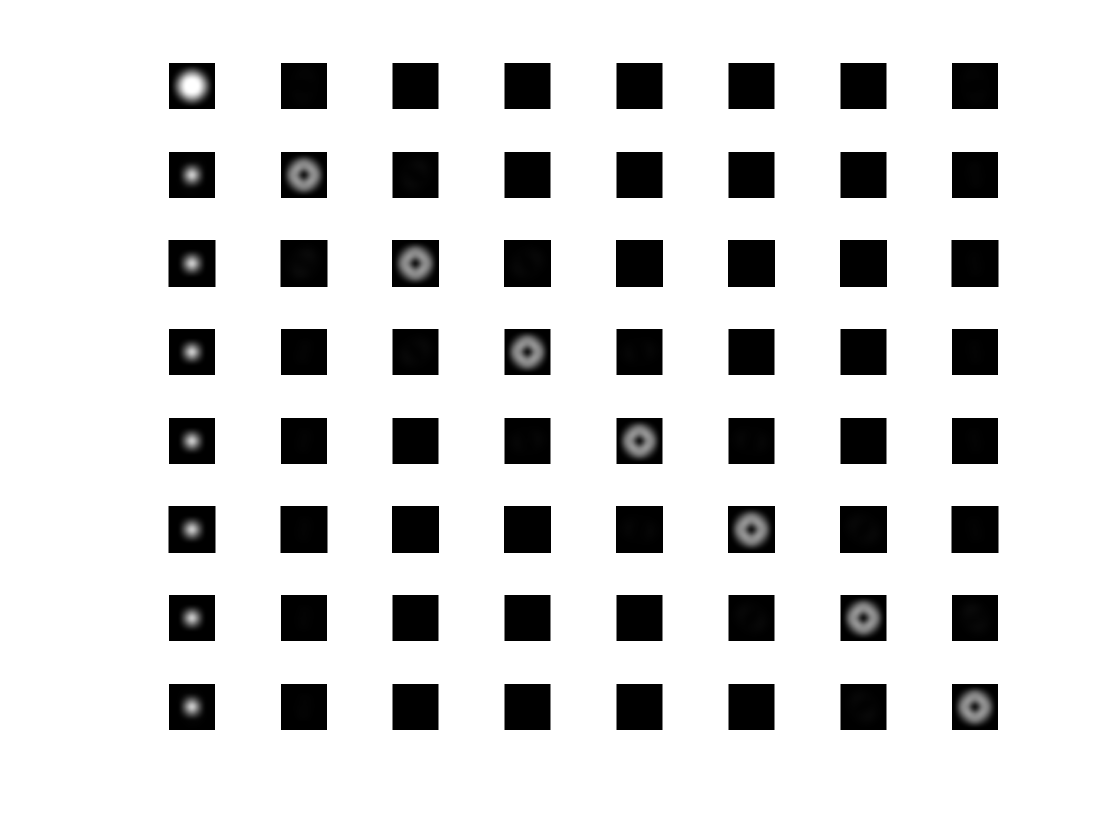

% example for the OTS model
whichCent = 1;
params = [.1, 1];
sig = params(1); alpha = params(2);
stim_idx = [1, 5];
sig_long  = .8;
sig_short  = .8;
sig_dot = .01;
F = kernel_weight(sig_long, sig_short, sig_dot, centerSize, 'oriTuned');

figure;
% X x Y x filtOrient x SurroundOrient
Z = NaN(size(surr_E,1), size(surr_E,2), size(surr_E,3), size(surr_E,4));
for ep = 1:nSurroundOrient
    % energy: x, y, neuron orient, center Orient, Surround orient
    E = surr_E(:, :, :, ep, whichCent);

    Z_thetas = NaN(size(E));
    
    for theta1 = 1:nOri
        Ztheta1 = 0;
        for theta2 = 1:nOri
            kernel_2d = F(:,:,theta1,theta2);
            image_theta = E(:,:,theta2);
            z_theta = conv2(image_theta, kernel_2d, 'same');
            Ztheta1 = Ztheta1 + z_theta;
        end
        Z_thetas(:,:,theta1) = Ztheta1;
    end
    
    Z(:,:,:,ep) = Z_thetas;
end

for ii = 1:nSurroundOrient
    for jj = 1:nOri
        subplot(nSurroundOrient, nOri, nOri*(ii-1)+jj), 
        imshow(Z(:,:,jj,ii), [0 max(Z(:))]),
    end
end


% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = squeeze(surr_E(:,:,:,:,whichCent)) ./ (sig + Z);

% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(cenMask .* D, [1, 2]));
% add exponential
s = d.^alpha;
% Response tuned for one center orientation influenced by different surround
% orientations
r_surround = s(whichCent,:);
 

## Normalized center responses

% X x Y x Orient x SurroundDiff
Z = NaN(size(tune_E,1), size(tune_E,2), size(tune_E,3), size(tune_E,4));
for ep = 1:nOri
    % energy: x, y, neuron orient, center Orient
    E = tune_E(:, :, :, ep);

    Z_thetas = NaN(size(E));
    
    for theta1 = 1:nOri
        Ztheta1 = 0;
        for theta2 = 1:nOri
            kernel_2d = F(:,:,theta1,theta2);
            image_theta = E(:,:,theta2);
            z_theta = conv2(image_theta, kernel_2d, 'same');
            Ztheta1 = Ztheta1 + z_theta;
        end
        Z_thetas(:,:,theta1) = Ztheta1;
    end
    
    Z(:,:,:,ep) = Z_thetas;
end

% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = squeeze(tune_E(:,:,:,:)) ./ (sig + Z);

% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(cenMask .* D, [1, 2]));
% add exponential
s = d.^alpha;
% Response to all center orientations for a neuron tuned to whichCent
r_center = s(:,whichCent);
 


#### Get the curves

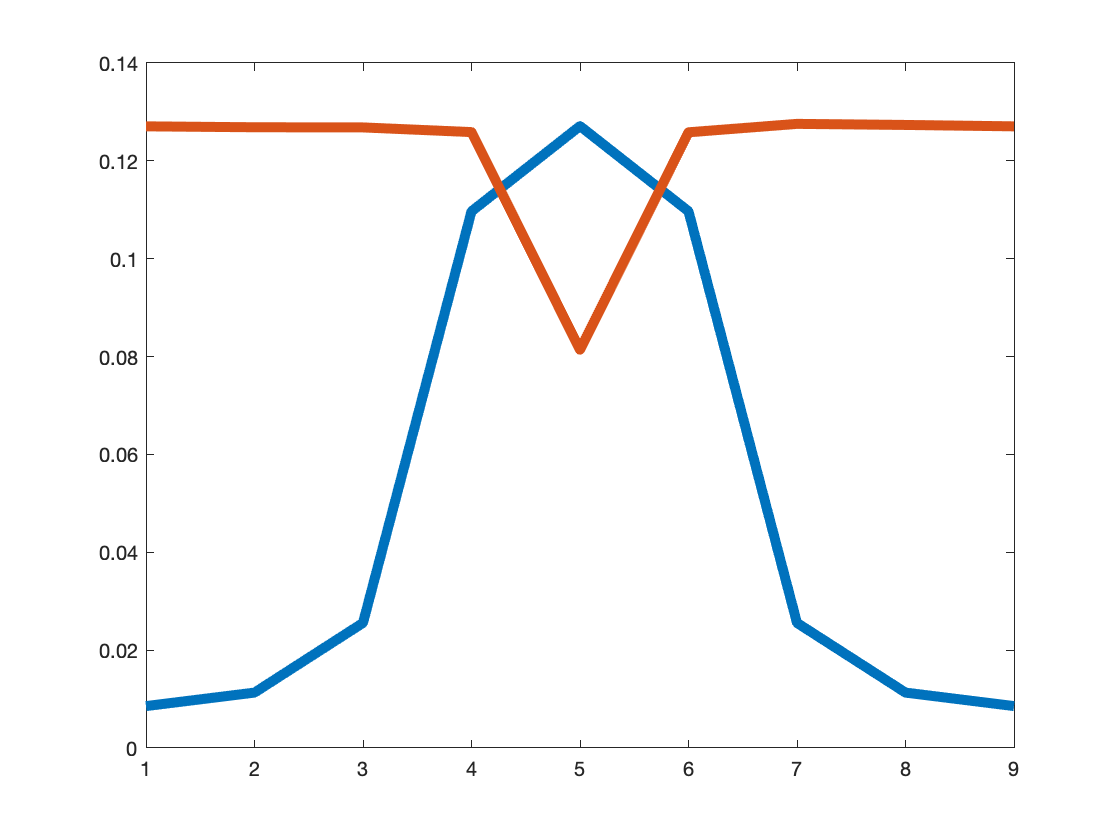


tune_curve      = zeros(1,nOri);
tune_curve(1:4) = r_center(5:8);
tune_curve(5:8) = r_center(1:4);

supp_curve      = zeros(1,nOri);
supp_curve(1:4) = r_surround(5:8);
supp_curve(5:8) = r_surround(1:4);

tune_curve2 = [tune_curve, tune_curve(1)];
supp_curve2 = [supp_curve, supp_curve(1)];

figure();
plot(tune_curve2,'LineWidth', 5)
hold on
plot(supp_curve2,'LineWidth', 5)

% yline(prefer_res, '-.k', 'LineWidth', 3)

#### A example 

% example for CE model
whichCent = 1;
params = [.1, 1];
sig = params(1); alpha = params(2);
% energy: % x, y, orient_channnel, surrOri, centOri
E = squeeze(surr_E(:,:,:,:,whichCent));
% get normalizer: Z = const
E_ori = mean(E, [1, 2]);
Z = std(E_ori, 1);
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = E ./ (sig + Z);
% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(cenMask .* D, [1, 2]));
% add exponential
s = d.^alpha;
% Filter orient x surround orient
r_surrNOA = s(whichCent,:); 

figure;
subplot(1, 3, 1)
imshow(squeeze(mean(E(:,:,1), 4)), [])
subplot(1, 3, 2)
imshow(squeeze(mean(D(:,:,1), 4)), [])
subplot(1, 3, 3)
imshow(squeeze(mean(cenMask.*D(:,:,1), 4)), [])

% energy: % x, y, orient_channnel, surrOri, centOri
E = squeeze(tune_E(:,:,:,whichCent));
% get normalizer: Z = const
E_ori = mean(E, [1, 2]);
Z = std(E_ori, 1);
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = E ./ (sig + Z);
% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(cenMask .* D, [1, 2]));
% add exponential
s = d.^alpha;
r_centNOA = s; 

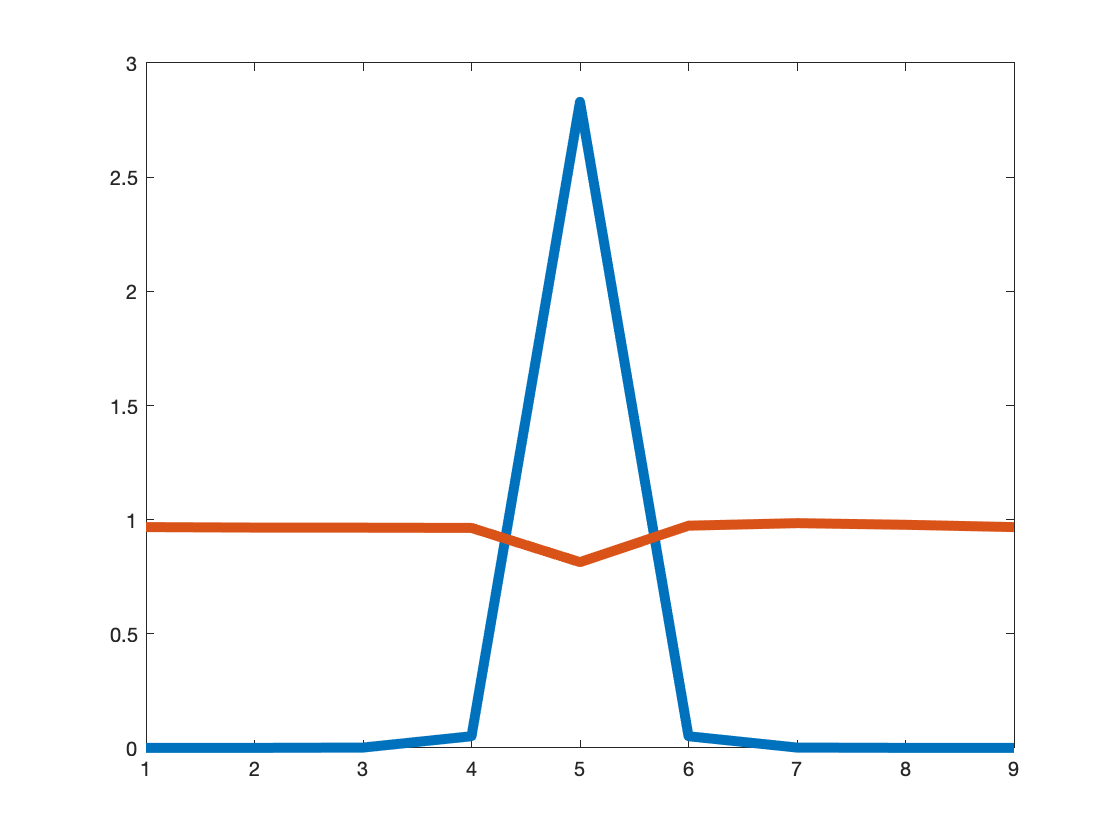

%
tune_curve      = zeros(1,nOri);
tune_curve(1:4) = r_centNOA(5:8);
tune_curve(5:8) = r_centNOA(1:4);

supp_curve      = zeros(1,nOri);
supp_curve(1:4) = r_surrNOA(5:8);
supp_curve(5:8) = r_surrNOA(1:4);

tune_curve2 = [tune_curve, tune_curve(1)];
supp_curve2 = [supp_curve, supp_curve(1)];

figure();
plot(tune_curve2,'LineWidth', 5)
hold on
plot(supp_curve2,'LineWidth', 5)